# createMetIntrcNetwork: Metabolite-Metabolite network function for COBRA

## **Author(s):**

Kadir Kocabas, Bioinformaticss and Systems Biology, Gebze Technical University, Turkey.

## **INTRODUCTION**

Visualization of metabolite interactions on graphs is a convenient way to trace of metabolites of interest. It provides significant advantages for  detecting produced and consumed metabolites with the help of colourization of edges based on flux values. createMetIntrcNetwork function is a cobra toolbox function for generation  metabolite-metabolite interaction network with given metabolites. If flux values are given, it produces directed metabolite-metabolite interaction network, and It adjust colour and width of edges in the network based on  flux values. The direction of arrows shows produced metabolites. On the produced graph, there is a colorbar that defines which colour corresponds to flux value (see Fig. 1). The scale of colorbar can be defined in order to produce comparable graph for different conditions. It allows to design graph with optional inputs such as node size and colour. Texts of nodes are clickable in the Produced figures. Different functionality was assigned for left and right click; 

**Left Click**: Generate sub-metabolite-metabolite network from the created figure, this functionality was added for better looking at the created network and showing flux values on edges lines. It is like zooming and adjusting position of clicked node and its first neighbors (see Fig. 2). 

**Right click**: Generate metabolite-metabolite interaction network from model, this functionality was added for creating metabolite-metabolite interacting network using clicked metabolite and model. It creates new network using clicked node (see Fig. 3). 

Another useful option is deleting edges based on given threshold value. ( see Fig 4).  The graphs can be created with nodes that has  degree in the given range with the help of excNodesWithDeg parameter (see Section 6).

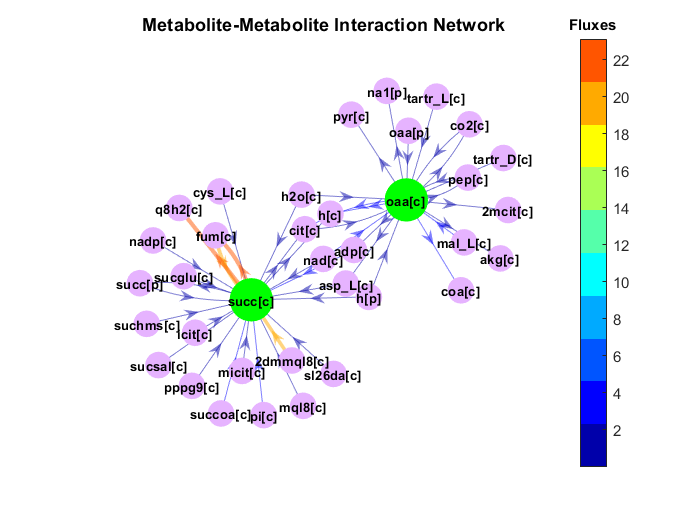

**Figure 1** : Succinate and oxaloacetate centered metabolite metabolite interaction network. Colour and width of edges determine based on flux values. Highlighted nodes with green colour represent given metabolites. The network produce using *Salmonella* genome scale metabolic model (Thiele et al. 2011).   

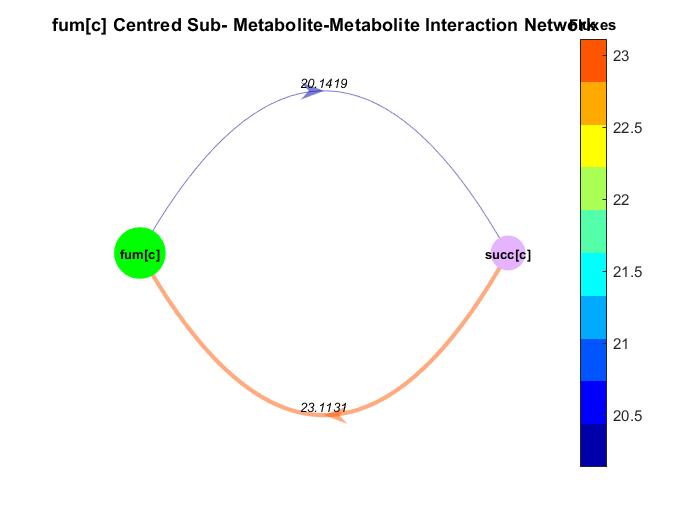

**Figure 2** :Figure that produced with left click on fum[c] in the Fig. 1. It only shows edges and nodes that connect to fum[c] in the previously produced network (Fig. 1). Values on the edges represent flux values. 

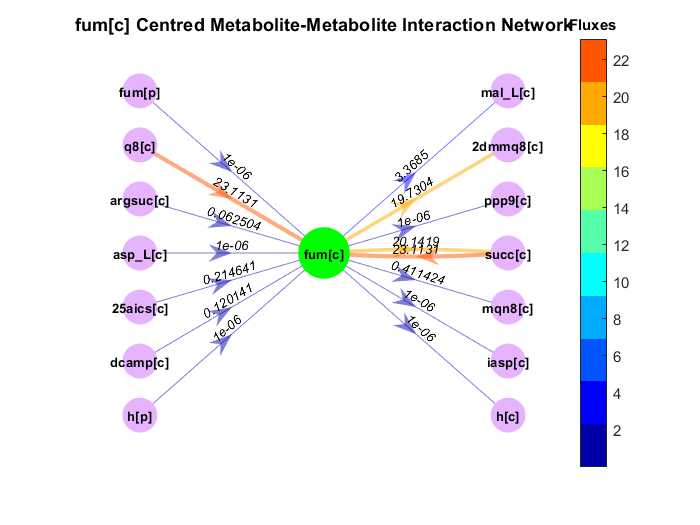

**Figure 3 :** Figure that produced with right click on fum[c] in the Fig. 1. It generates new metabolite-metabolite interaction netwrok using fum[c]. It shows all relationships of fum[c] in the model. Values on the edges represent flux values. 1e-6 represents zero flux since weight of edges cannot be 0 in the matlab graph objects.

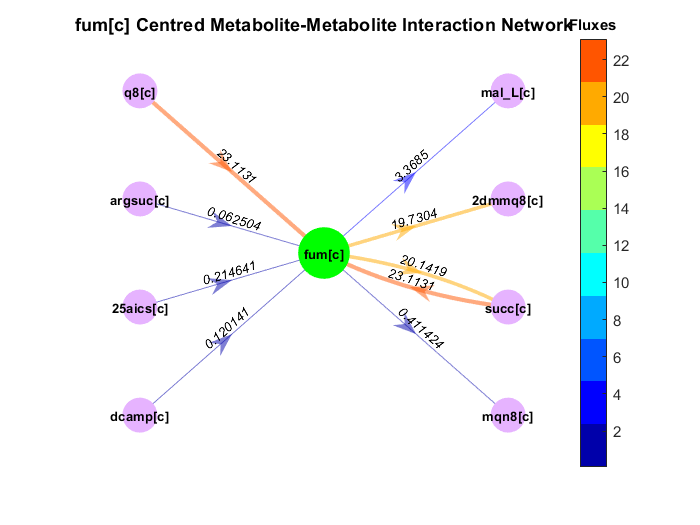

**Figure 4 **:  Figure that produced with right click on fum[c] in the Fig 1. The edges with 0 fluxes were deleted using threshold optional input. 

## MATERIALS 

No materials are needed as createMetIntrcNetwork is a software product.

## **EQUIPMENT**

The equipment has to be able to run MATLAB.

**EQUIPMENT SETUP**

The COBRA toolbox is required to use the createMetIntrcNetwork.

**PROCEDURE**

Initialise COBRA toolbox, change solver and Load models. 

initCobraToolbox(false) %don't update the toolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.24.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver ('gurobi', 'all', 1);


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018a.
 > changeCobraSolver: Solver for MIQP problems has been set to gurobi.
 > changeCobraSolver: Solver gurobi not supported for problems of type NLP. Currently used: matlab 


%changeCobraSolver ('glpk', 'all', 1);



The model is available at https://www.ebi.ac.uk/biomodels/MODEL1507180017#Files (Thiele et al. 2011).  Download the model file in the working directory. You can also use your own model.

model = readCbModel('MODEL1507180017_url.xml');

**Section 1: **

Producing Metabolite-metabolite interaction network for succinate, fumarate and oxaloacetate without flux values. 

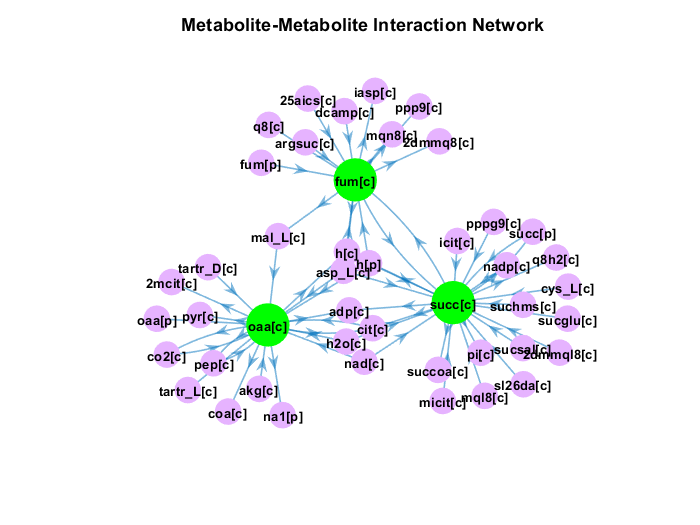

mets={'succ[c]','oaa[c]','fum[c]'}; % metabolites of interest.
graphObj=createMetIntrcNetwork(model,mets);

**Section 2: **

Optimization of the objective function by using the COBRA toolbox  command  optimizeCbModel, where the argument  model corresponds to the COBRA model in the MATLAB workspace.

FBAsolution = optimizeCbModel(model);
fluxes=FBAsolution.x;


Creating Metabolite-metabolite interaction network for succinate, fumarate and oxaloacetate with flux values. 

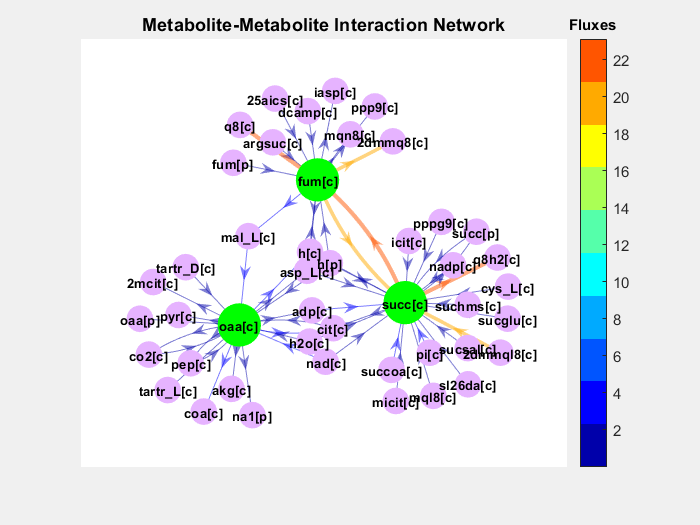

graphObj=createMetIntrcNetwork(model,mets,'fluxes',fluxes);
set(gcf,'Visible','on'); % produce figure as pop up since live editor does

                         % not allow clicking on figure in the editor.

Colour and width of edges determine based on flux values. Highlighted nodes with green colour represent given metabolites. Colorbar is created based on flux values. 

Another network will be produce if left click on the mal_L[c] on the produced network. The new network will be sub-metabolite-metabolite network of the previous one. This plot was added as statically since live editor does not allow clicking on figure in the editor.But if the codes were written in the previous section is run, it will be produced the figure as pop up, and it will be clickable. Figures that produced from main figure also can be clickable with the same properties.

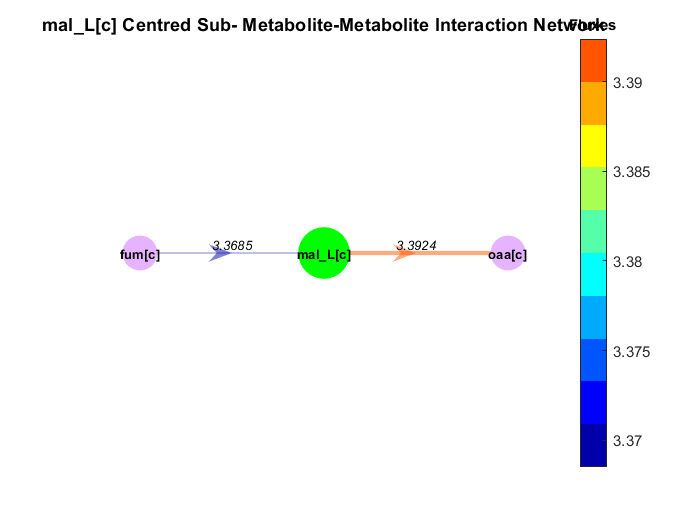

Another network will be produce if right click on the mal_L[c] on the produced network. The new network will be metabolite-metabolite interaction network from model.  It creates new network using clicked node. This plot was added as statically since live editor does not allow clicking on figure in the editor.But if the codes were written in the previous section is run, it will be produced the figure as pop up, and it will be clickable. Figures that produced from main figure also can be clickable with the same properties.

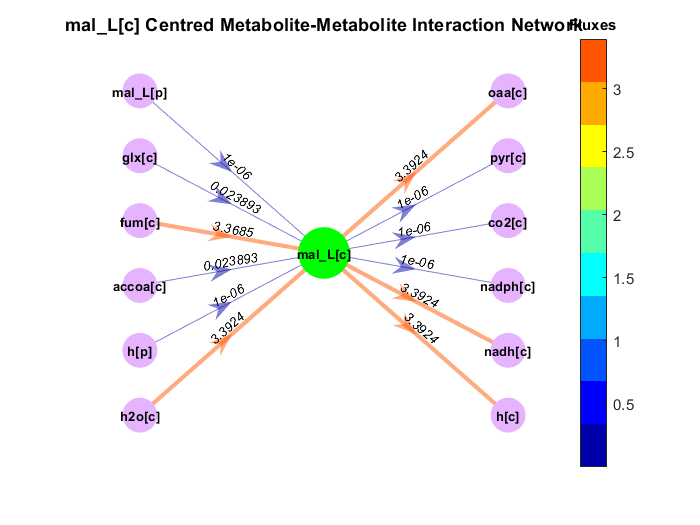

**Section 3: **

Generating more clear network via excluding desired metabolites atp[c], adp[c],nad[c],nadh[c],h2o[c], na1[p], nadp[c], h[c],co2[c] and pi[c]. 

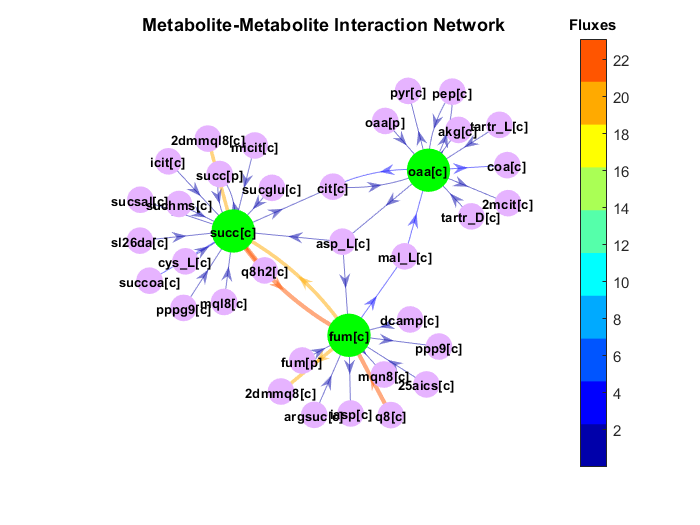

excludedMets={ 'atp[c]', 'adp[c]','nad[c]','nadh[c]','h2o[c]' 'pi[c]','h[p]'...
    ,'na1[p]','nadp[c]','h[c]','co2[c]'};
graphObj=createMetIntrcNetwork(model,mets,'fluxes',fluxes,'excludedMets',excludedMets);

**Section 4: **

Scaling colorbar to produce comparable networks with different conditions. 

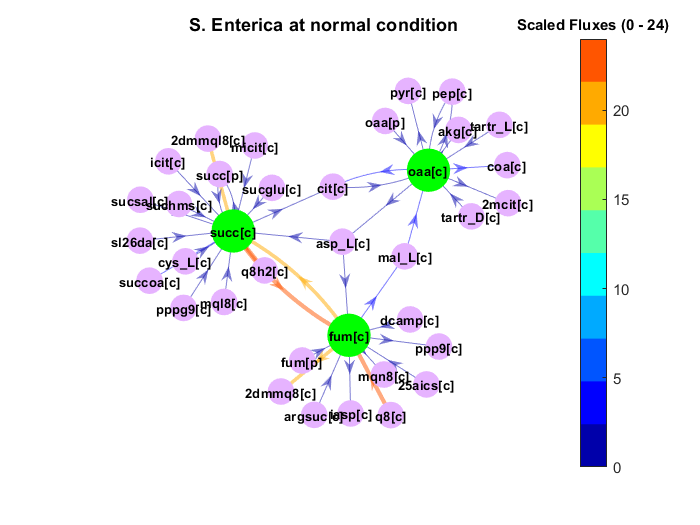

title='S. Enterica at normal condition'; % defining title for network
scaleMin=0; % define minimum value for colorbar
scaleMax=24;%define maximum value for colorbar
graphObj=createMetIntrcNetwork(model,mets,'fluxes',fluxes,'excludedMets'...
    ,excludedMets,'Graphtitle',title,'scaleMin',scaleMin,'scaleMax',scaleMax);

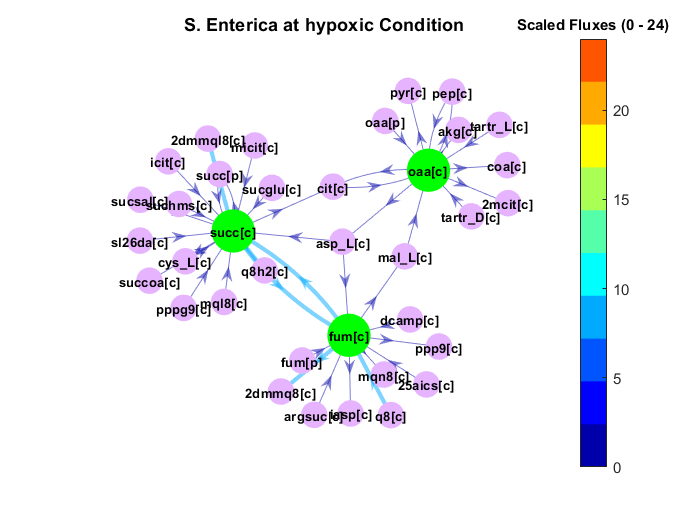

modelhpx=model;% assigning model to modelhpx.
modelhpx.lb(872)=model.lb(872)/4; % decreasing O2 exchange to 
                                  % 1/4 for comparing different condition
                                  
FBAsolutionhpx = optimizeCbModel(modelhpx); % optimize model in hypoxic condition.
fluxeshpx=FBAsolutionhpx.x; % getting flux values 
title='S. Enterica at hypoxic Condition'; % defining title for network 
graphObjhpx=createMetIntrcNetwork(modelhpx,mets,'fluxes',fluxeshpx,'excludedMets',...
    excludedMets,'Graphtitle',title,'scaleMin',scaleMin,'scaleMax',scaleMax);

As a result, the flux between succ[c] and fum[c] decreases in hypoxia, and it can be seen with looking at the figures.

**Section 5: **

Generating network with deleting edges based on given threshold value. Threshold value was determined as 0 to exclude edges with no fluxes. After deleting edges, the nodes with zero degree will be deleted.

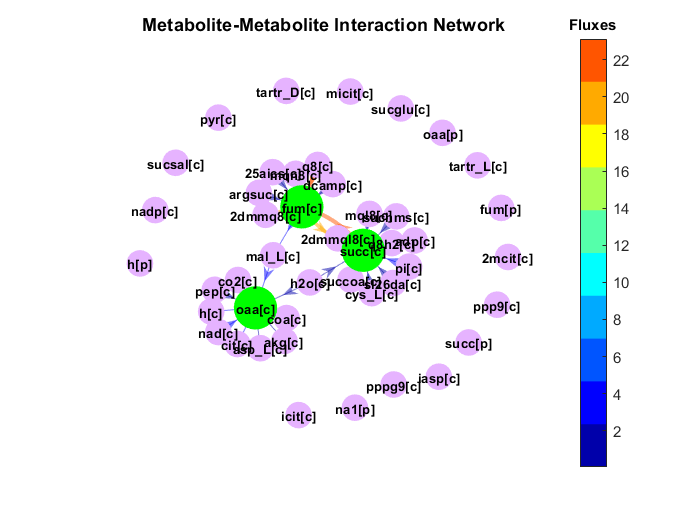

graphObj=createMetIntrcNetwork(model,mets,'fluxes',fluxes,'threshold',0);

**Section 6: **

Deleting nodes that has not degree in a given range. It can be used for better visualization or excluding very employed metabolites.

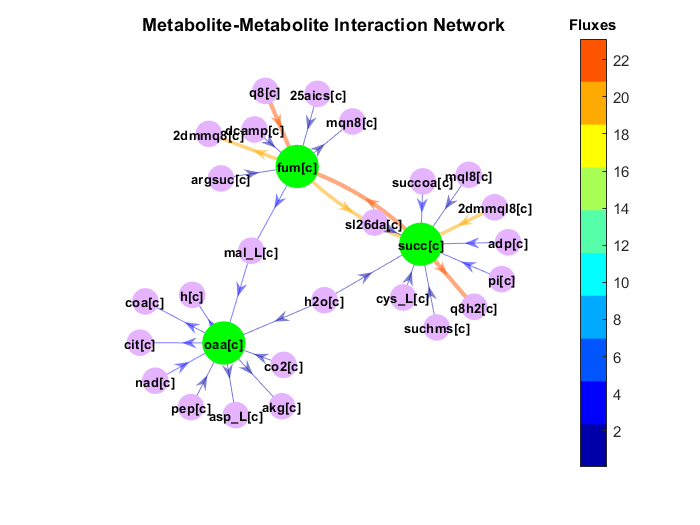

nodeDegreeRange=[1 50]; % deleting nodes that has lower than 1 degree 
                        % and higher than 100 degree.
graphObj=createMetIntrcNetwork(model,mets,'fluxes',fluxes,'threshold'...
    ,0,'excNodesWithDeg',nodeDegreeRange);

As a consequence, better network was generated with excluding nodes that has not degree in a given range. 

**Section 7 :**

Modifying figures. Figures can be produced based on desired design. There is 6 optional parameters for designing figures; 

**Graphtitle** : Change Title of figure, **nodeColour** : change colour of nodes (it should be RGB triplet see  https://www.mathworks.com/help/matlab/ref/colorspec.html), **Hnodecolour**: change colour of higlighted nodes(it should be RGB triplet), **nodeSize** : change  size of nodes, **HnodeSize**: change size of higlighted nodes, **arrowSize**: change arrow size.

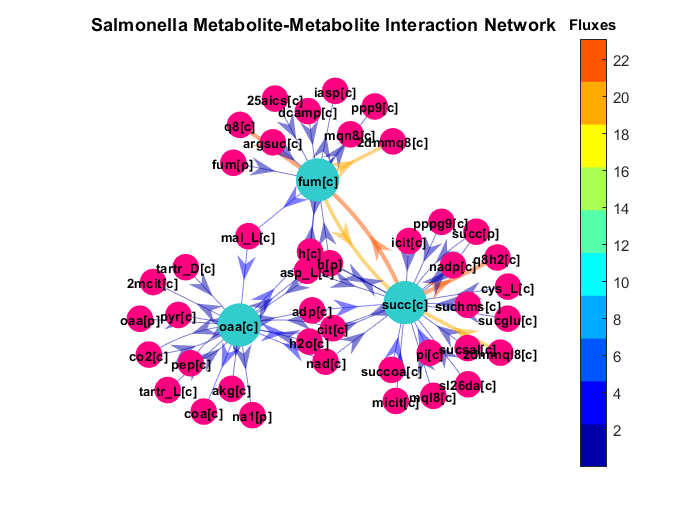

Graphtitle='Salmonella Metabolite-Metabolite Interaction Network';
nodeColour=[1 0 0.5];
Hnodecolour=[0.2 0.8 0.8];
nodeSize=15;
HnodeSize=25;
arrowSize=15;
graphObj=createMetIntrcNetwork(model,mets,'fluxes',fluxes,'Graphtitle',Graphtitle,...
    'nodeColour',nodeColour,'Hnodecolour',Hnodecolour,'nodeSize',nodeSize,'HnodeSize'...
    ,HnodeSize,'arrowSize',arrowSize);

**Section 8 :**

Creating Metabolite metabolite interaction network with all metabolites inside the model. It can be useful for detecting metabolites that has not interaction with other metabolites, and more advanced network analysis techniques can be perform using produced graph object. 

graphObj=createMetIntrcNetwork(model,model.mets);

Code was written in text format since matlab live editor cannot produce such big network. Figures were added as static.

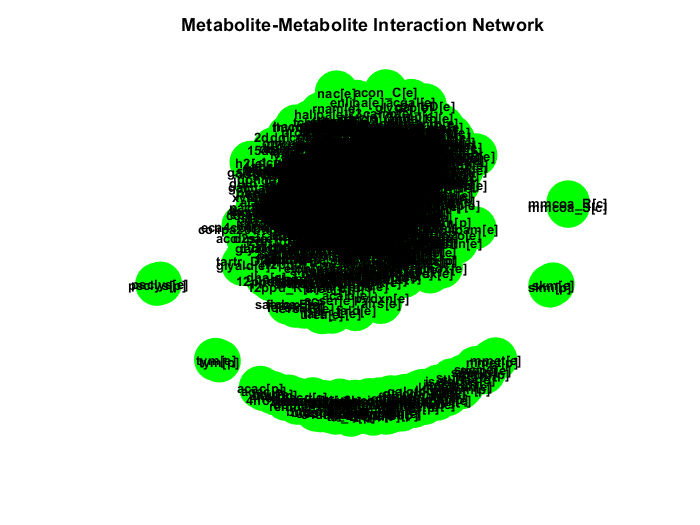

The metabolites that has not interaction with other metabolites can be easily detected by clicking on nodes that placed far from center of the network (see figure below). 

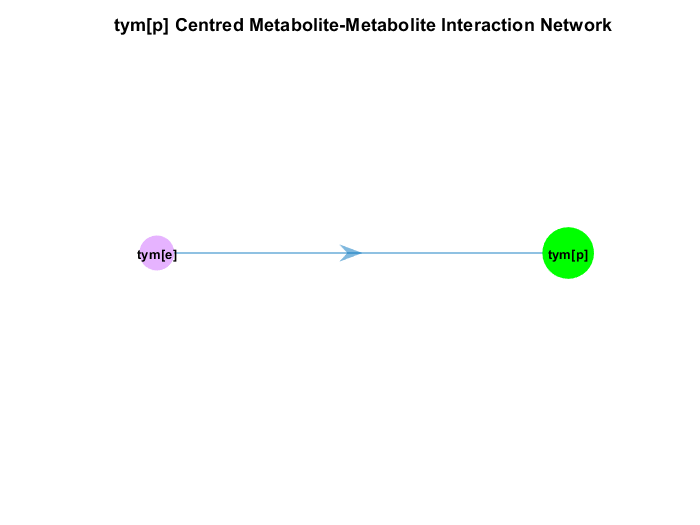

**TROUBLESHOOTING**

The function was written with warning and error messages. The messages are explanatory for troubles (see anticipated results).

**TIMING**

The function was written without using loops to increase performance.  The function can be considered as efficient since it can produce graph consisting 1800 node and 6812 edges within 9 seconds in the Matlab editor(intel i5 9th generation,16 GB ram). 

**ANTICIPATED RESULTS**

**1.**The function will produce a warning message if the given metabolites are not defined inside the model. But function will produce the network without undefined metabolites.

mets={'succ[c]','oaa[c]','fum[c]','x','y'}; % metabolites of interest.
graphObj=createMetIntrcNetwork(model,mets);

**2.**The function will produce a error message if the inputs not properly defined.

mets={'succ[c]','oaa[c]','fum[c]'}; % metabolites of interest.
graphObj=createMetIntrcNetwork(model,mets,'nodeSize','g');

Error using createMetIntrcNetwork (line 98)
The value of 'nodeSize' is invalid. It must satisfy the function: isnumeric.

**3.**The function will produce a warning message if there is not edges in the network.

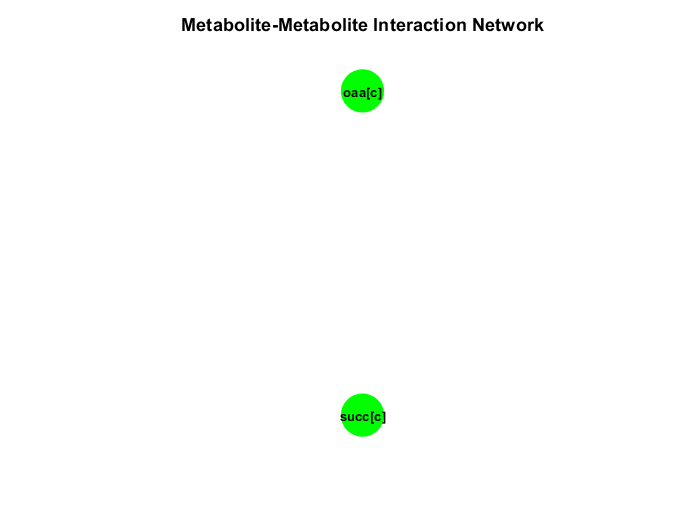

graphObj=createMetIntrcNetwork(model,mets,'excNodesWithDeg',[20 100]);

**4.**The function will produce a warning message if scales are given without giving fluxes.

graphObj=createMetIntrcNetwork(model,mets,'scaleMin',0,'scaleMax',10);

**5.**The function will produce a error message if scaleMin bigger than scaleMax.

graphObj=createMetIntrcNetwork(model,mets,'scaleMin',10,'scaleMax',0);

Error using createMetIntrcNetwork (line 116)
scaleMax should bigger than scaleMin

**6.**The function will produce a error message if excNodesWithDeg are given wrong as minimum degree bigger than maximum degree.

graphObj=createMetIntrcNetwork(model,mets,'excNodesWithDeg',[10 0]);

Error using createMetIntrcNetwork (line 120)
maximum degree should bigger or equal to minimum degree

`REFERENCES`

Thiele I, Hyduke DR, Steeb B, Fankam G, Allen DK, Bazzani S, Charusanti P, Chen FC, Fleming RM, Hsiung CA, De Keersmaecker SC, Liao YC, Marchal K, Mo ML, Özdemir E, Raghunathan A, Reed JL, Shin SI, Sigurbjörnsdóttir S, Steinmann J, Sudarsan S, Swainston N, Thijs IM, Zengler K, Palsson BO, Adkins JN, Bumann D. A community effort towards a knowledge-base and mathematical model of the human pathogen Salmonella Typhimurium LT2. BMC Syst Biol. 2011 Jan 18;5:8.